# Detectores Ópticos

Convierten energía eléctrica en óptica.

- Fuentes de banda ancha (Espectro continuo)

- Fuentes de luz monocromática incoherente (LEDs)

- Fuentes de luz monocromática coherente (Láser)

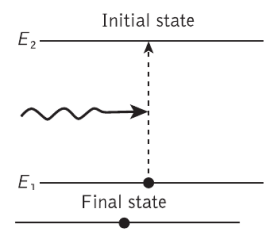


$$E=E_2 -E_1 =h\;f$$



$$h=6\ldotp {626*10}^{-34}$$



$$E_{1\;} \to \textrm{Estado}\;\textrm{normal}$$



$$E_2 \to \textrm{Estado}\;\textrm{excitado}$$


Si la energía del fotón obedece a la ecuación el fotón es absorbido

## LEDs


$$E=h\;f$$



$$\lambda \left(m\right)=\frac{h\;c}{\textrm{Eg}}$$



$$\textrm{Con}\;\textrm{Eg}\;\textrm{en}\;\textrm{eV}\;y\;\lambda \;\textrm{en}\;\mu m\;\lambda =\frac{1\ldotp 24}{\textrm{Eg}\;}$$


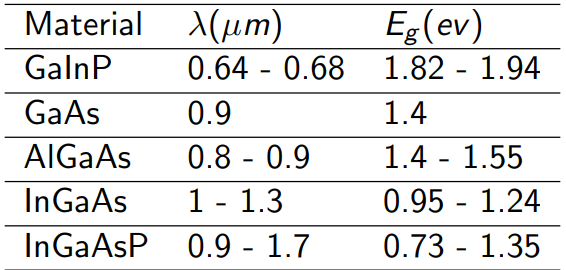

## Características de operación

### Potencia óptica


$$P=\eta \;N\;\textrm{Eg}$$


N: número de cargas inyectadas por segundo$N=\frac{i}{e}$

Si Eg está en eV: $P=\eta \;\textrm{Eg}\;i$

## Modulación Analógica

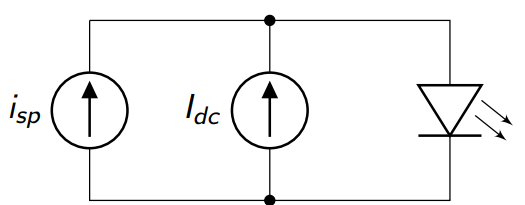


$$i=I_{\textrm{dc}} +I_{\textrm{sp}} \;\textrm{sen}\left(\textrm{wt}\right)$$



$$P=P_{\textrm{dc}} +P_{\textrm{sp}} \;\textrm{sen}\left(\textrm{wt}\right)$$


## Láser

Ligtht Amplification by the Simulated Emission of Radiation


$$\frac{\textrm{N1}}{\textrm{N2}}=\frac{g_1 \;e^{-\;\frac{E_1 }{K\;T}} }{g_2 \;e^{-\;\frac{E_2 }{K\;T}} }=\frac{g_1 }{g_2 }{\;e}^{\frac{E_2 -E_1 }{K\;T}} =\frac{g_1 }{g_2 }\;e^{\frac{h\;f}{K\;T}}$$


g: degeneraciones de los niveles

K: constante de Boltzan $\left(1\ldotp 3806488*{10}^{-23} \frac{J}{K}\right)$

# Detectores Ópticos

## Responsividad


$$\rho =\frac{i}{P}$$


$\rho \;$: responsividad

i: corriente de salida del detector

P: potencia óptica de entrada

## Respuesta espectral

Curva de responsividad del detector en función de la longitud de onda

## Tiempo de subida

tr: tiempo de subida

Demora de subir del 10% al 90%, a 3 dB la señal de salida cae a la mitad en relación a bajas frecuencias


$$f_{3\textrm{dB}} =\frac{0\ldotp 35}{\textrm{tr}}$$


## Longitud de onda de corte

Permite determinar si el detector permite trabajar con una longitud de onda, energía mínima que debe tener un fotón para ser detectado. Máxima longitud de onda detectable


$$\lambda {\;}_c =\frac{1\ldotp 24}{\;E_g }\to \textrm{Si}\;E_{g\;} \;\textrm{está}\;\textrm{en}\;\textrm{electrón}\;\textrm{voltios},\textrm{dando}\;\textrm{así}\;\textrm{en}\;\mu m$$



$$\lambda {\;}_c =\frac{h\;c}{\textrm{Eg}}$$


## Eficiencia cuántica

No siempre $h\;f\ge \textrm{Eg}$ libera suficientes electrones para ser detectados, este parámetro define la relación de electrones emitidos con los fotones incidentes.

n = electrones emitidos/fotones incidentes


$$\eta =\frac{\textrm{electrones}\;\textrm{emitidos}}{\textrm{fotones}\;\textrm{incidentes}}$$



$$\eta =\frac{\textrm{re}}{\textrm{rp}}$$



$$\textrm{rp}=\frac{P}{h\;f}$$



$$\textrm{re}=\frac{n\;P}{h\;f}$$


P: potencia óptica

hf: energía de 1 fotón


$$i=\frac{\eta \;e\;P}{h\;f}=\frac{n\;e\;\lambda \;P}{h\;c}$$



$$e=1\ldotp 602*10^{-19} \;\to \textrm{Carga}\;\textrm{del}\;\textrm{electrón}$$



$$\rho =\frac{\eta \;e}{h\;f}=\frac{\eta \;e\;\lambda }{h\;c}$$


## Fotodiodo de vacío


$$v=\frac{\eta \;e\;P\;R\;L}{h\;f}=\rho \;\;P\;R\;L$$



$$\begin{array}{l}
M=\delta^N \\
i=\frac{M\;\eta \;e\;P}{h\;f}=\frac{M\;n\;e\;\lambda \;P}{h\;c}
\end{array}$$



clear
clc

e = 1.602e-19;
h = 6.626e-34;

N = 9;
n = 0.01;
g = 5;
P = 1e-6;
lambda = 0.8e-6;
M = g^N;
i = M * n * e * lambda * P/(h * 3e8);
Rho = i/P;
v = i * 50;

L=20 km

Uniones cada 4 Km (1 dB por desalineación)

cada extremo perdidas de 1 dB por conectores

$\alpha \;$=1dB/km

Pin=3.981 mW

El detector tiene eficiencia cuántica del 40%

El enlace opera a 850 nm

La corriente oscura del detector es de 3 nA

Calcular corriente del detector

Si el circuito de detección tiene un voltaje de 5 V y una resistencia de 1Kohm, determinar la potencia mínima y máxima de detección.

Mínima potencia de entrada para el enlace anterior

clear
clc

L=20e3;
i_Dark=3e-9;

Uniones=4;
alpha=20;
conectores=2;

Pin=3.981e-3;

Sist=Uniones+alpha+conectores;
Pin=10*log10(Pin/1e-3);

Pout=Pin-Sist;
Pout=10^(-2)*1e-3;

n=0.4;
lambda=850e-9;

e = 1.602e-19;
h = 6.626e-34;

rho=n*e*lambda/(h*physconst('lightspeed'));
corriente_detector=rho*Pout;

VB=5;
RL=1e3;
Pmax=VB/(rho*RL);

Pmin=i_Dark/rho;

Pmin=10*log10(Pmin/1e-3);
Pmin=Pmin+Sist;
Pmin=10^(Pmin/10)*1e-3;

## Ruido en comunicaciones ópticas

### Ruido térmico

Se presenta en la resistencia de carga del receptor, esto debido a que los electrones se mueven aleatoriamente debido a la temperatura, la potencia media disipada se puede obtener con:


$$P=R_L *\bar{i_{\textrm{NT}}^2 } =4\;K*T*\Delta f$$



$$\Delta f:\textrm{ancho}\;\textrm{de}\;\textrm{banda}\;\textrm{eléctrico}\;\textrm{del}\;\textrm{receptor}$$


### Ruido Shot

El pulso que presenta al hacer el tránsito de un electrón del ánodo al cátodo, el tiempo de este pulso se denomina $\tau$


$$i_{\mathrm{NS}}^2 =2\;e\;*I*\;\Delta f=2e\left(\bar{i_S } +I_D \right)\Delta \;f$$


$I:$ Corriente promedio generada y corriente oscura

La SNR se calcula según dos situaciones:

- Potencia óptica constante (1 en PCM)

- Potencia variable senoidalmente (señal analógica modulada)

Es mejor utilizar un fotodiodo con ganancia interna, como lo es el fotodiodo de avalancha

La potencia eléctrica sobre RL es:


$$P_{\mathrm{ES}} =i_S^2 *\mathrm{RL}$$


La potencia por ruido Shot promedio es: $P_{\mathrm{NS}} =2*e*\Delta \;f\;\left(\frac{\eta \;e\;P}{h\;f}+I_D \right)*\mathrm{RL}$

La potencia para ruido térmico es: $P_{\mathrm{NT}} =4\;K\;T\;\Delta \;f$


$$\frac{S}{N}=\frac{P_{\mathrm{ES}} }{P_{\mathrm{NS}} +P_{\mathrm{NT}} }$$


Ej.:

1 LED que emite 10 mW a 850 nm, el cable de fibra tiene 20 dB de perdidas, 1 fotodetector TIN con responsividad de 0.5 $\frac{A}{W}$, la corriente oscura del detector es de 2 nA, se utiliza una resistencia de 50 ohm y el ancho de banda, T=300 K; $\Delta \;f=$10 MHz, perdidas por acoples de 14 dBm y 10 más debido a conectores

P=? en detector

i=? señal detectada

P=? señal eléctrica detectada

Ruidos termicos y shot

SNR

clear
clc

e = 1.602e-19;
h = 6.626e-34;
k=1.38e-23;
T=300;
Df=10e6;
lambda=850e-9;
Pin=10e-3;
Pin=10*log10(Pin/1e-3);
i_Dark=2e-9;

Pout=Pin-20-10-14;
Pout=10^(Pout/10)*1e-3

Pout =    398.1072e-009


rho=0.5;
RL=50;
is=rho*Pout

is =    199.0536e-009


PRL = RL * is^2

PRL =      1.9811e-012


PNS=2*e*(is+i_Dark)*Df

PNS =    644.1757e-021


PNT=4*k*T*Df

PNT =    165.6000e-015


SNR=PRL/(PNS+PNT)

SNR =     11.9632e+000


Repetir reduciendo perdidas, hacer tabla variando potencia de receptor y cambiando potencia de recepción